% Encryption
img = imread("lena_std.tiff");
imgbinary = str2double(reshape(cellstr(dec2bin(img)), size(img)))

imgbinary = imgbinary(:,:,1) =

    11100010    11100010    11011111    11011111    11100010    11100010    11100100    11100011    11100011    11100001    11100100    11100001    11011111    11100010    11011111    11011101    11011101    11011101    11011110    11011110    11011111    11011111    11100000    11011101    11011010    11011101    11011111    11100001    11011101    11011101    11011100    11011111    11100001    11011111    11100010    11011111    11100001    11100011    11100101    11100111    11100111    11101000    11100110    11101001    11101010    11101101    11101001    11100111    11101101    11101110    11101010    11101011    11101010    11101000    11101001    11100110    11100011    11011101    11011011    11010101    11001011    11001010    10111011    10101110    10101001    10100110    10011110    10011001    10011011    10011101    10100110    10100001    10100110    10100101    10101001    10101010    10101110    10101110    10101111    10110100    1011

message = 'helloworld'

message = 'helloworldkdsjdsansndjdiqdasdkkadsmksdmkasdmadsmkmdskmdskmsdmskdmaskdmdksmsadkmasdkmdaskmdsakmdaskmadskadmsmadsmdskmdsakmdsamkdaskasdmasdmkdsmasdmkdskmadsmkjnsdjnsdjndsjnsndjsndjdnsjdsjnsdnjsdjndsjnsdjndejdieqdijqeidjqedjqeidjijdisnsdnsdinsd'

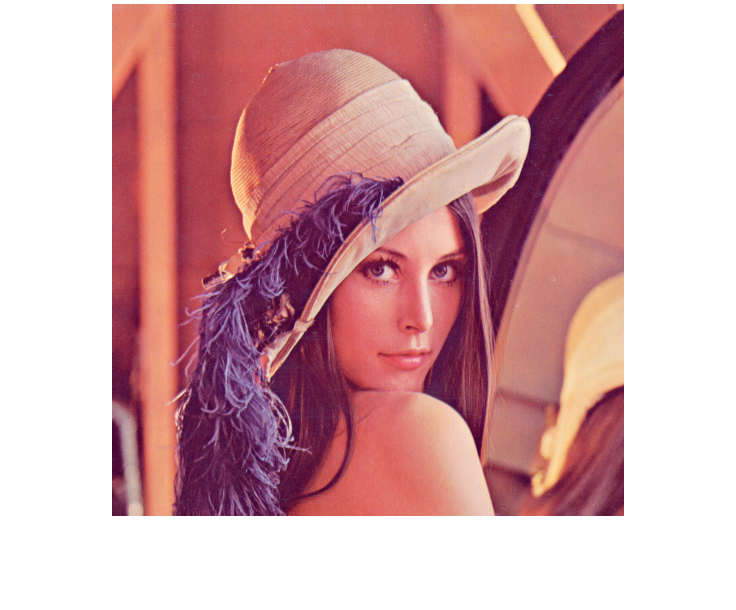

inputascii = double(message);
shiftascii = inputascii + 3;
binary = reshape(dec2bin(shiftascii, 8).'-'0',1,[]);
dash = [0 0 1 0 1 1 0 1];
[maxrows, maxcolumns, maxpages] = size(img);
binarywdash = [binary dash dash dash];
counter = 1; rows = 1; columns = 1; page = 1;
while counter < (length(binarywdash)+1)
    if mod(double(img(rows,columns,page)), 2) < binarywdash(1,counter)
        imgbinary(rows,columns,page) = imgbinary(rows,columns,page) + 1;
    elseif mod(double(img(rows,columns,page)), 2) > binarywdash(1,counter)
        imgbinary(rows,columns,page) = imgbinary(rows,columns,page) - 1;
    end
    page = page + 1;
    if page == 4
        columns = columns + 1;
        page = 1;
    end
    if columns == maxcolumns + 1
        rows = rows + 1;
        columns = 1;
    end
    counter = counter + 1;
end
imshow("lena_std.tiff")

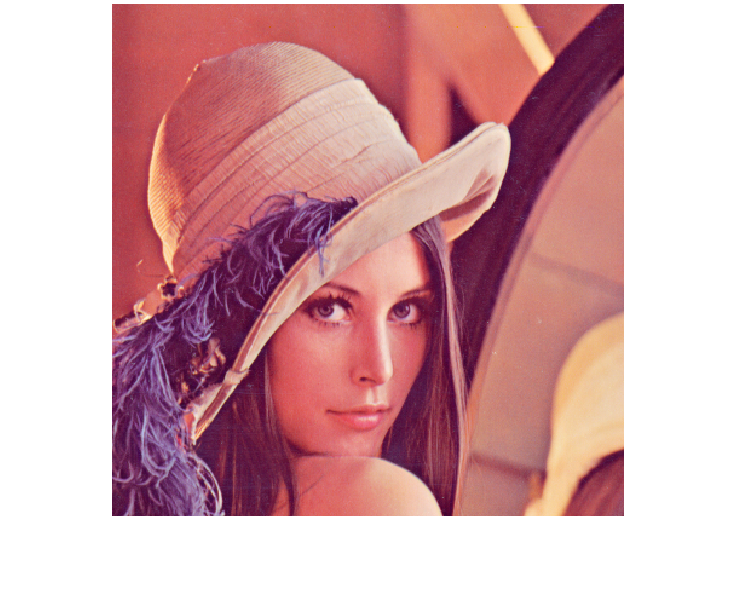

imgwmessage = uint8(bin2dec(string(imgbinary(:,:,:))));
imwrite(imgwmessage,"lena_message.tiff");
imshow(imgwmessage)

% Decryption
imgdec = imread("lena_message.tiff");
imgdecbinary = str2double(reshape(cellstr(dec2bin(imgdec)), size(imgdec)));
dashcounter = 0; rows = 1; columns = 1; page = 1; eightcounter = 1; msgcolumns = 1;
decryptedmsg = [];
msg = [];
save = "";
while dashcounter < 3
    save = strcat(save,string(mod(double(imgdecbinary(rows,columns,page)), 2)));
    page = page + 1;
    if page == 4
        columns = columns + 1;
        page = 1;
    end
    if columns == maxcolumns + 1
        rows = rows + 1;
        columns = 1;
    end
    eightcounter = eightcounter + 1;
    if eightcounter == 9
        if bin2dec(save) == 45
            dashcounter = dashcounter + 1;
        else
            msg(1,msgcolumns) = bin2dec(save) - 3;
            msgcolumns = msgcolumns + 1;
        end
        save = "";
        eightcounter = 1;
    end 
end
decryptedmsg = char(msg)

decryptedmsg = 'helloworldkdsjdsansndjdiqdasdkkadsmksdmkasdmadsmkmdskmdskmsdmskdmaskdmdksmsadkmasdkmdaskmdsakmdaskmadskadmsmadsmdskmdsakmdsamkdaskasdmasdmkdsmasdmkdskmadsmkjnsdjnsdjndsjnsndjsndjdnsjdsjnsdnjsdjndsjnsdjndejdieqdijqeidjqedjqeidjijdisnsdnsdinsd'